# Sensuator: A Hybrid Sensor-Actuator Approach to Soft Robotic Proprioception Using Recurrent Neural Networks

This is simple tutorial for loading our data, preprocessing the data, training the model and using the model to predict outputs.

#### Setting our options

Firstly, we set our options. These will be used later in the script.

% Which network do we want to build/train?
opt_training = TrainingOptions.BiLSTM;
% For our GRU, LSTM and BiLSTM networks, how many hidden units do we want
% per layer?
opt_hidden_units = 100;
% For our MLP network, what size do we want for each layer?
opt_mlp_size = 20;
% How long do we train for in epochs?
opt_max_epoch = 50;

We have a pretrained model, set this to **true** to re-train from scratch.

opt_retrain = false;

Plot colors (for later use)

global plot_tools;
plot_tools.color(1,:) = [227,26,28]./255; % Red
plot_tools.color(2,:) = [51,160,44]./255; % Green
plot_tools.color(3,:) = [31,120,180]./255; % Blue
plot_tools.color(4,:) = [152,78,163]./255; % Purple
plot_tools.color(5,:) = [255,127,0]./255; % Orange

### Loading the data

Now we can load our data into memory. 

train_data = csvread('train_data.csv');
test_data = csvread('test_data.csv');

As a sanity check, we will check the size of each dataset.

size(train_data)

ans =        46672          21


size(test_data)

ans =        30000          21


The first column is the pressure sensor's reading. The next 6 columns are each ConTact sensor's voltage. And the 8th-14th & 15th - 21st column are the X and Y coordinates in pixels for each LED, respectively.

We can plot what the raw data looks like:

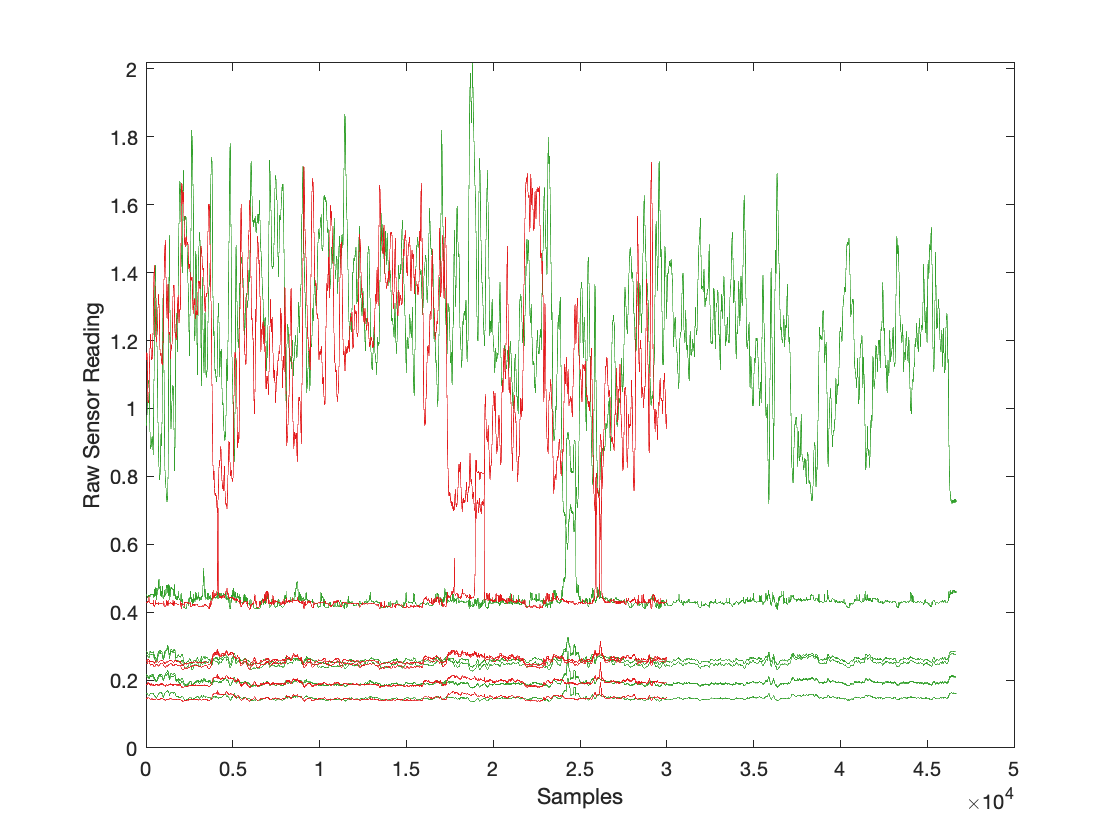

figure;
plot(train_data(:,1:7), 'Color', [51,160,44]./255); hold on; % Green
plot(test_data(:,1:7), 'Color', [227,26,28]./255); % Red
xlabel('Samples');
ylabel('Raw Sensor Reading');

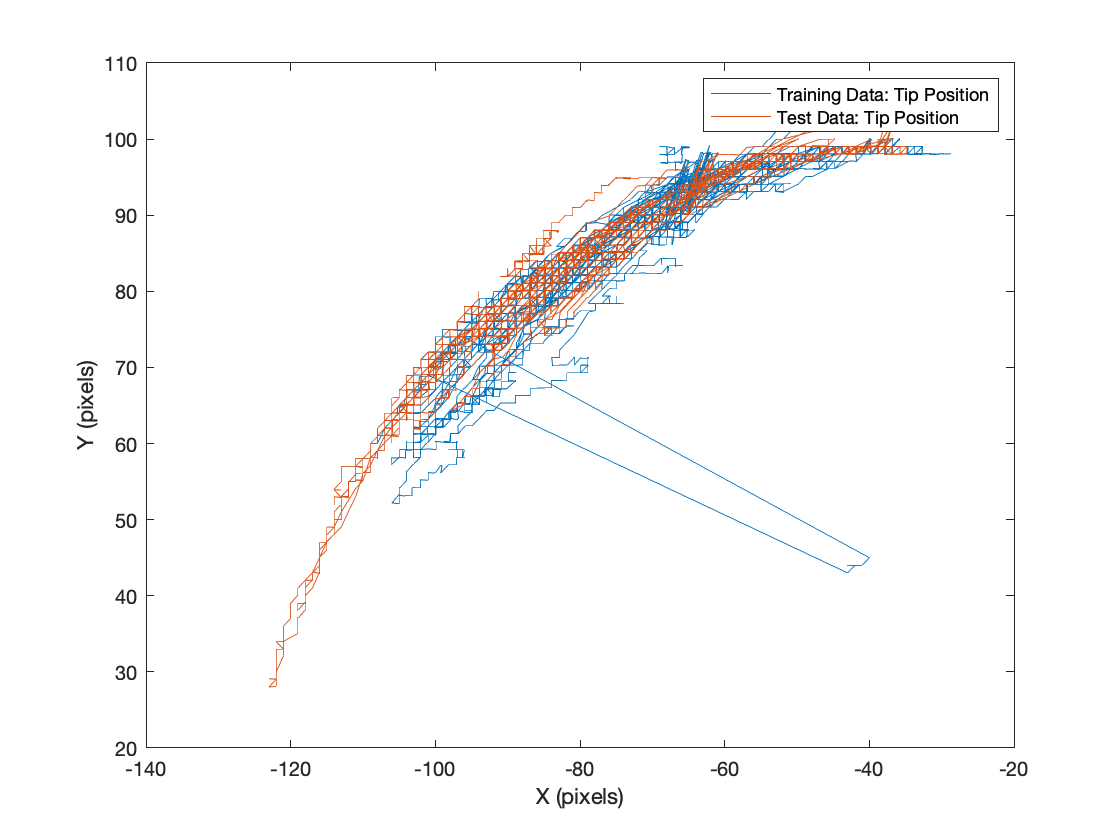

figure;
plot(train_data(:,14), train_data(:,21)); hold on;
plot(test_data(:,14), test_data(:,21));
xlabel('X (pixels)');
ylabel('Y (pixels)');
legend('Training Data: Tip Position', 'Test Data: Tip Position');

### Preprocessing the data

We first split our training data to set aside a validation set. Here we'll do a simple 80/20 split.

ratio = 0.8;
len_train_data = length(train_data);
split_idx = floor(ratio*len_train_data);
train_idx = 1:split_idx;
val_idx = split_idx+1:len_train_data;

Let's specify our columns so we can use them later too. X and Y are basically our inputs and outputs to our model (not to be confused with the coordinates)

x_col = 1:7;
y_col = 8:21;

We also want the size of these for our network parameters

outputs = length(y_col);
inputs = length(x_col);

Now we can put our data into their respective variables

x_train = train_data(train_idx, x_col);
y_train = train_data(train_idx, y_col);

x_val = train_data(val_idx, x_col);
y_val = train_data(val_idx, y_col);

x_test = test_data(:, x_col);
y_test = test_data(:, y_col);

#### Normalization

Let's use simple z-score normalization to normalize our data to zero mean and unit variance. Note that we use the values from the training data to normalize our test data.

x_bar = mean(x_train);
x_sd = std(x_train);
x_train = (x_train - x_bar) ./ x_sd;
x_val = (x_val - x_bar) ./ x_sd;

y_bar = mean(y_train);
y_sd = std(y_train);
y_train = (y_train - y_bar) ./ y_sd;
y_val = (y_val - y_bar) ./ y_sd;

x_test = (x_test - x_bar) ./ x_sd;
y_test = (y_test - y_bar) ./ y_sd;

#### Smoothing

For the training data only, let's smooth out the raw data so our network learns better. We use 3rd order Butterworth low pass filter with a cutoff at 5 Hz. We do **not** do the same with the test data. 

fs = 50; % Sampling frequency (Hz)
fc = 5; % Low pass cut-off frequency (Hz)
Wn = fc/(fs/2);
[b,a] = butter(3, Wn, 'low'); % 3rd order Butterworth low pass filter
% Filtfilt is used to negate any phase shift caused by the filter
x_train = filtfilt(b,a,x_train);
y_train = filtfilt(b,a,y_train);
x_val = filtfilt(b,a,x_val);
y_val = filtfilt(b,a,y_val);

Lastly, we have to transpose the data for the Deep Learning Toolbox.

x_train = x_train';
y_train = y_train';

x_val = x_val';
y_val = y_val';

x_test = x_test';
y_test = y_test';

### Constructing the network

Now let's construct our network based on the options we chose above. We can also construct these networks using the **Deep Network Designer **tool.

switch opt_training
    case TrainingOptions.LSTM
        layers = [ ...
            sequenceInputLayer(inputs)
            lstmLayer(opt_hidden_units)
            fullyConnectedLayer(outputs)
            regressionLayer];
    case TrainingOptions.GRU
        layers = [ ...
            sequenceInputLayer(inputs)
            gruLayer(opt_hidden_units)
            fullyConnectedLayer(outputs)
            regressionLayer];
    case TrainingOptions.BiLSTM
        layers = [
            sequenceInputLayer(inputs)
            bilstmLayer(opt_hidden_units)
            fullyConnectedLayer(outputs)
            regressionLayer];
    case TrainingOptions.MLP
        layers = [
            sequenceInputLayer(inputs)
            fullyConnectedLayer(inputs)
            fullyConnectedLayer(opt_mlp_size)
            reluLayer()
            fullyConnectedLayer(opt_mlp_size)
            reluLayer()
            fullyConnectedLayer(opt_mlp_size)
            reluLayer()
            fullyConnectedLayer(opt_mlp_size)
            reluLayer()
            fullyConnectedLayer(outputs)
            regressionLayer];
end

Then we set our hyperparameters. We've set these parameters to the values presented in the paper (Table 1).

opts = trainingOptions('adam', ...
    'MaxEpochs',opt_max_epoch, ... 
    'MiniBatchSize', 512,... 
    'GradientThreshold',10, ...
    'ValidationData',{x_val,y_val}, ...
    'ValidationFrequency',5, ...
    'InitialLearnRate',0.01, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',5, ...
    'LearnRateDropFactor',0.5, ...
    'Verbose',0, ...
    'Plots','training-progress', 'ExecutionEnvironment', 'cpu');

### Training

It's time to train! This will take a while if you have retrain set to true.

if isfile('sensuator_model.mat') && ~opt_retrain
    load('sensuator_model.mat');
else
    [net, net_info] = trainNetwork(x_train, y_train, layers, opts);
    % Save the model for later use. (Plotting, experiments, degradation, etc.)
    save('sensuator_model', 'net', 'net_info');
end

### Using the model

Let's now use the model to predict pixels from sensor data!

Firstly, let's fit our training data, to see how it performs with our training data.

[net_train_fit, y_pred_train] = predictAndUpdateState(net, x_train);

Then, let's give our test data a try

[net_test_fit, y_pred_test] = predictAndUpdateState(net, x_test);

### De-normalization of the outputs

Let's de-normalize our data so we can plot it.

y_pred_train_plot = y_pred_train';
y_pred_train_plot = (y_pred_train_plot .* y_sd) + y_bar;
y_train_plot = y_train';
y_train_plot = (y_train_plot .* y_sd) + y_bar;

y_test_plot = y_test';
y_test_plot = (y_test_plot .* y_sd) + y_bar;
y_pred_test_plot = y_pred_test';
y_pred_test_plot = (y_pred_test_plot .* y_sd) + y_bar;

% Save the data for later use. So we don't have to run everything again
% just to generate new plots.
save('model_plot_data','y_pred_train_plot','y_train_plot','y_test_plot','y_pred_test_plot');

### Sanity check: Plotting the training data

Now let's take a peek at how well our model performs with the training data

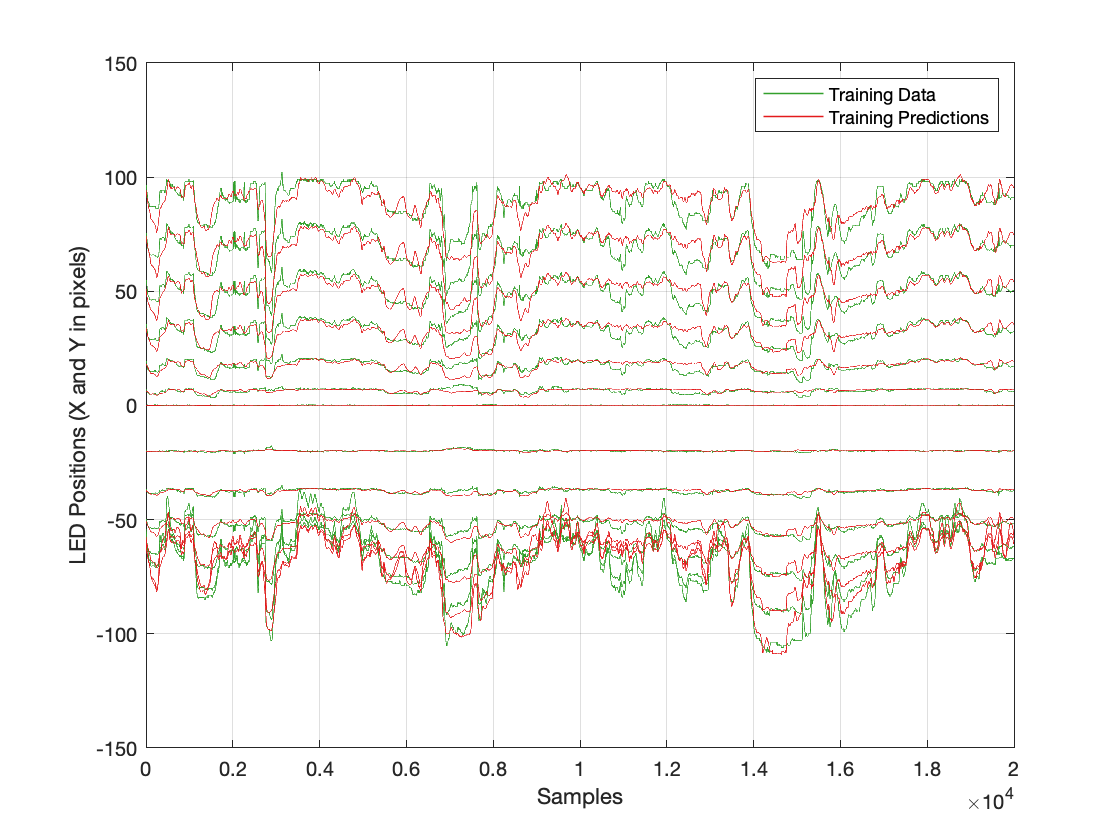

figure(3); hold on; grid on; box on;

plot_time = 10001:30000;
plot(y_train_plot(plot_time,1),'Color', plot_tools.color(2,:), 'LineWidth', 0.8);
plot(y_pred_train_plot(plot_time,1),'Color', plot_tools.color(1,:), 'LineWidth', 0.8);
plot(y_train_plot(plot_time,2:14),'Color', plot_tools.color(2,:), 'LineWidth', 0.8);
plot(y_pred_train_plot(plot_time,2:14),'Color', plot_tools.color(1,:), 'LineWidth', 0.8);
xlabel('Samples');
ylabel('LED Positions (X and Y in pixels)');
xlim([0 20000])
legend('Training Data', 'Training Predictions');

Not bad!

### Trying the model on the test data

Now let's try the test data:

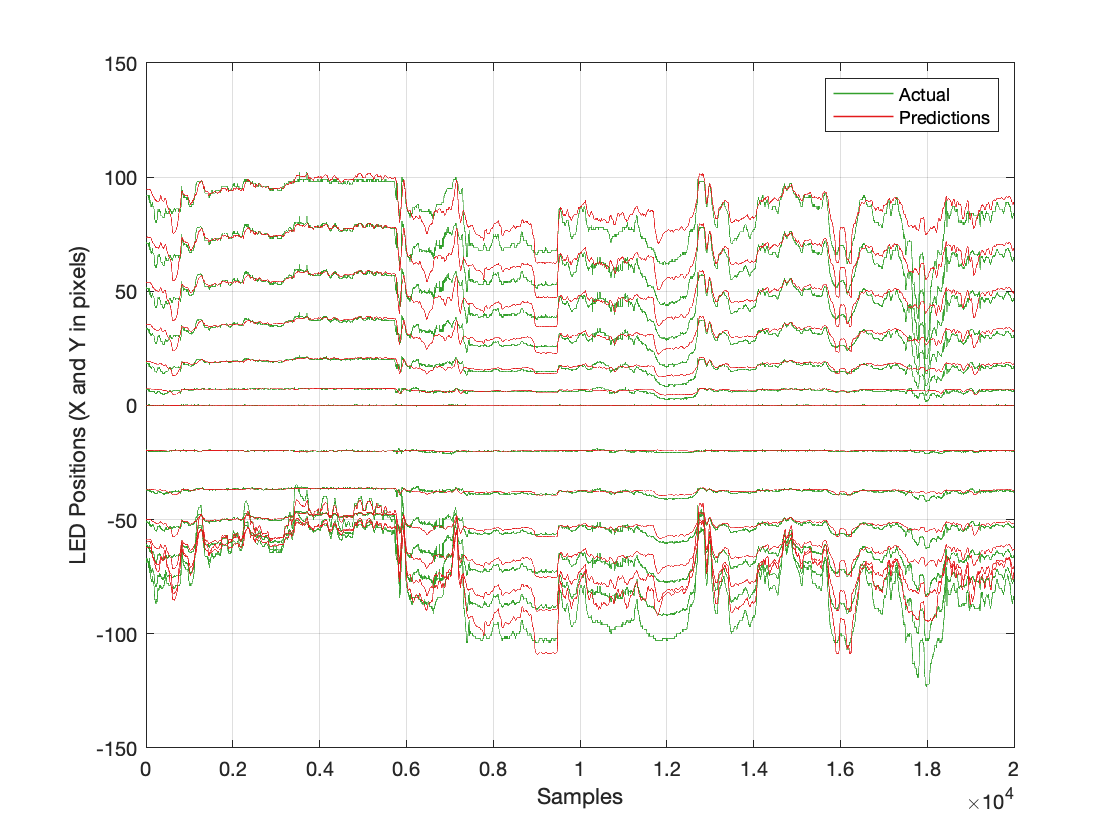

figure(4); clf; hold on; grid on; box on;

plot_time = 10001:30000;
plot(y_test_plot(plot_time,1),'Color', plot_tools.color(2,:), 'LineWidth', 0.8);
plot(y_pred_test_plot(plot_time,1),'Color', plot_tools.color(1,:), 'LineWidth', 0.8);
plot(y_test_plot(plot_time,2:14),'Color', plot_tools.color(2,:), 'LineWidth', 0.8);
plot(y_pred_test_plot(plot_time,2:14),'Color', plot_tools.color(1,:), 'LineWidth', 0.8);
xlabel('Samples');
ylabel('LED Positions (X and Y in pixels)');
xlim([0 20000])
legend({'Actual', 'Predictions'},'location','NorthEast');

And that's a wrap!